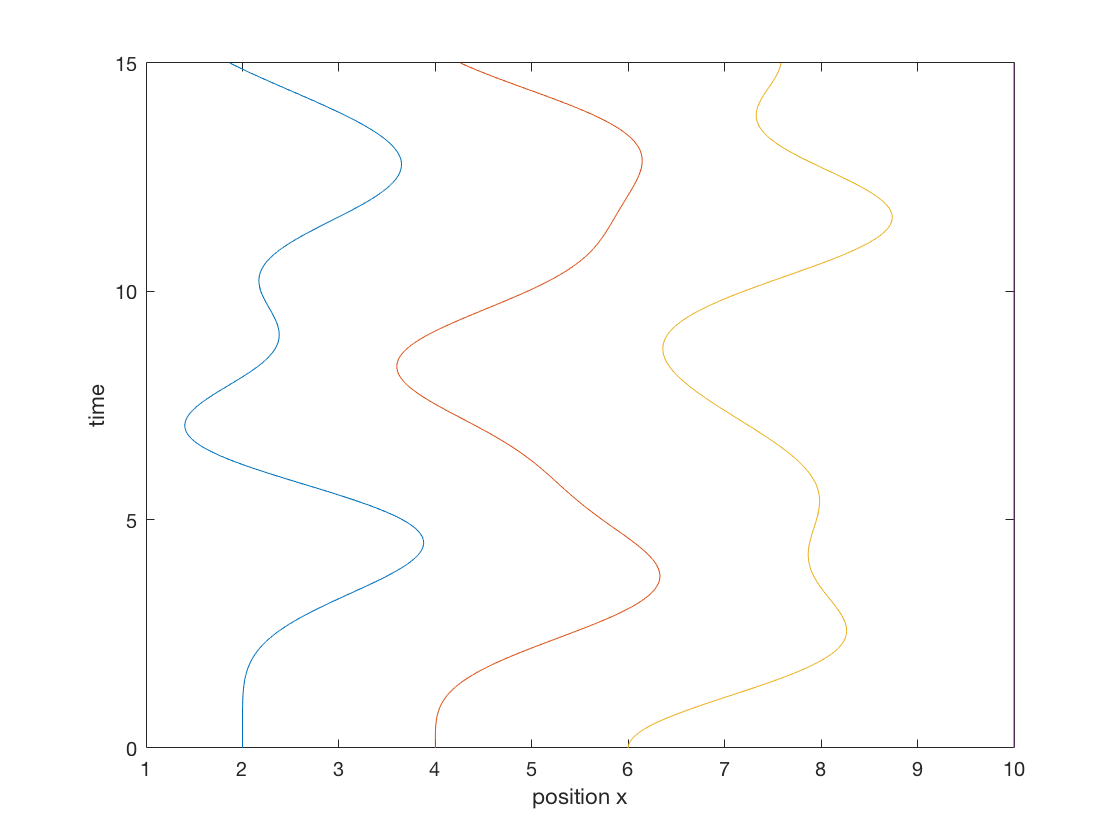

clear all; close all;
%Set system parameters
% E-k-m-k-m-k-m-xw
% We consider a linear chain of 3 particles of mass m = 1 
% connected to each other by a spring of stiffness k = 1. 
% The distance between the particles at the beginning is xe = 2. 
% The first and the last particle are connected to a wall: 
% the one on the left is fixed, 
% the other one is moved very slowly by a distance xw = xe 
% from its equilibrium position and then fixed in that position. 
k = 1; %stifness of the spring
m = 1; %mass
xe = 2; %equilibrium lenght
%Set initial conditions
x0 = 0; x4 = 5*xe; %position of the walls
x10 = xe; x20 = 2*xe; x30 = 3*xe; %initial position of the particles 
v10 = 0; v20 = 0; v30 = 0; %initial velocity of the particles
x_zero = [x10 x20 x30]; %initial position vector
v_zero = [v10 v20 v30]; %initial velocity vector
%Set simulation parameters
tf =15; %time of simulation
delta_t =0.01; %time step
Nt = ceil(tf/delta_t); %number of time increments
%Initialize the loop variables
for n = 1 : Nt+1
    if n == 1
        x(n,:) = [x0, x_zero, x4];
        v(n,:) = [0, v_zero, 0];
        for j = 1 : 5
            if j == 1
                f(n,j) = 0;
            elseif j >=2 & j<=4
                f(n,j) = (k * (x(n,j+1) - 2 * x(n,j) + x(n,j-1)));
              
            else
                f(n,j) = 0;
            end
        end
      
        a(n,:) = f(n,:) ./ m;
        alfa(n,:) = x(n,:) + (delta_t * v(n,:)) + (0.5 * a(n,:) * ...
        (delta_t^2)); %uniformly accelerated motion
    else
        x(n,:) = alfa(n-1,:);
        for j = 1 : 5
            if j == 1
                f(n,j) = 0 ;
            elseif j >=2 & j<=4
            f(n,j) =(k * (x(n,j+1) - 2 * x(n,j) + x(n,j-1)));%Verlet 
            else
            f(n,j) = 0;
            end
        end

a(n,:) = f(n,:) / m;
alfa(n,:) = (2 * x(n,:)) - x(n-1,:) + ((delta_t^2) * a(n,:));
v(n,:) = (alfa(n,:) - x(n-1,:))/(2 * delta_t);
    end
end
      %Analytical solution
x_rel = x(:,2) - x(:,1) - xe; 
x_an = -2:0.1:2;
F1 = k * x_an;
%Conservation of energy
for n = 1 : Nt+1
Ek1(n,1) = 0.5 * m * (v(n,2))^2; %kinetic energy of mass1 
Ek2(n,1) = 0.5 * m * (v(n,3))^2; %kinetic energy of mass2 
Ek3(n,1) = 0.5 * m * (v(n,4))^2; %kinetic energy of mass2 
Ek(n,1) = Ek1(n,1) + Ek2(n,1) + Ek3(n,1); % system kinetic energy 
Ep(n,1) = (0.5 * k * (x(n,2) - x(n,1) - xe)^2) + ...
(0.5 * k * (x(n,3) - x(n,2) - xe)^2) + ...
(0.5 * k * (x(n,4) - x(n,3) - xe)^2) + ...
(0.5 * k * (x(n,5) - x(n,4) - xe)^2); % system potential energy 
Etot(n,1) = Ek(n,1) + Ep(n,1); %total energy
end
t=(0:Nt)*delta_t;

%visu
plot(x(:,2:end),t);xlabel('position x');ylabel('time');

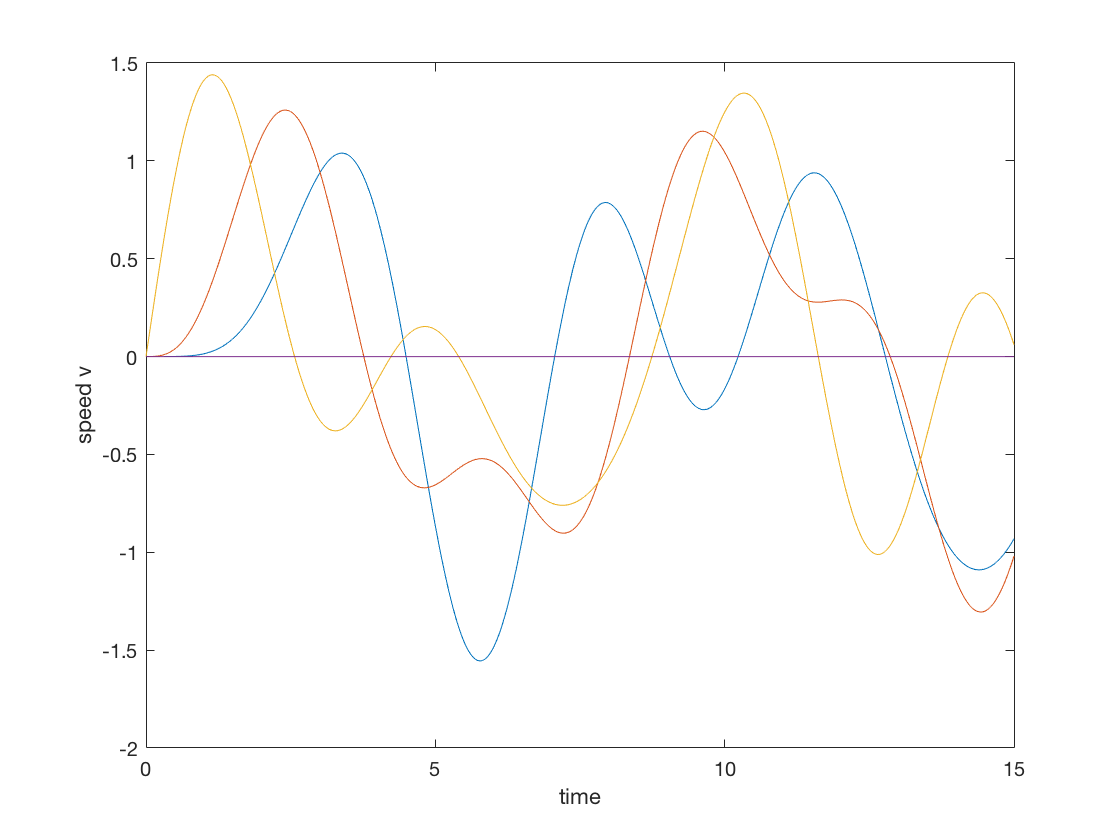


figure;
plot(t,v(:,2:end));ylabel('speed v');xlabel('time');

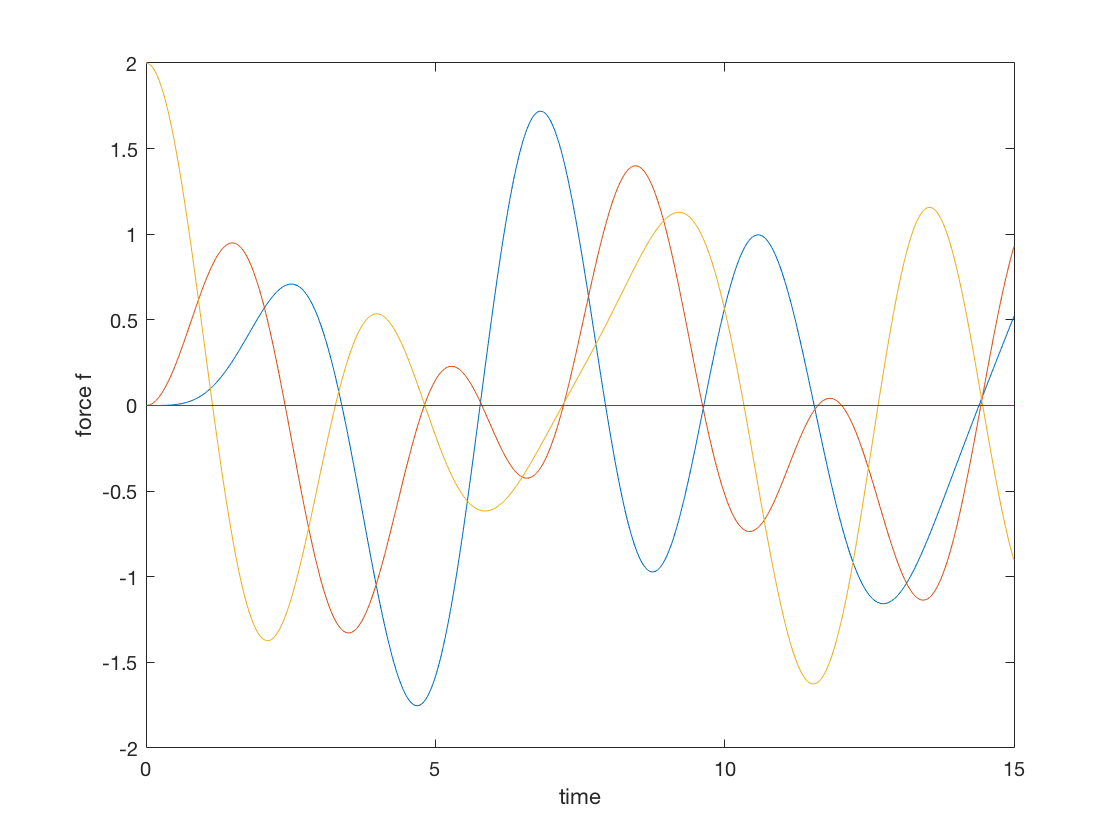


figure; 
plot(t,f(:,2:end));ylabel('force f');xlabel('time');

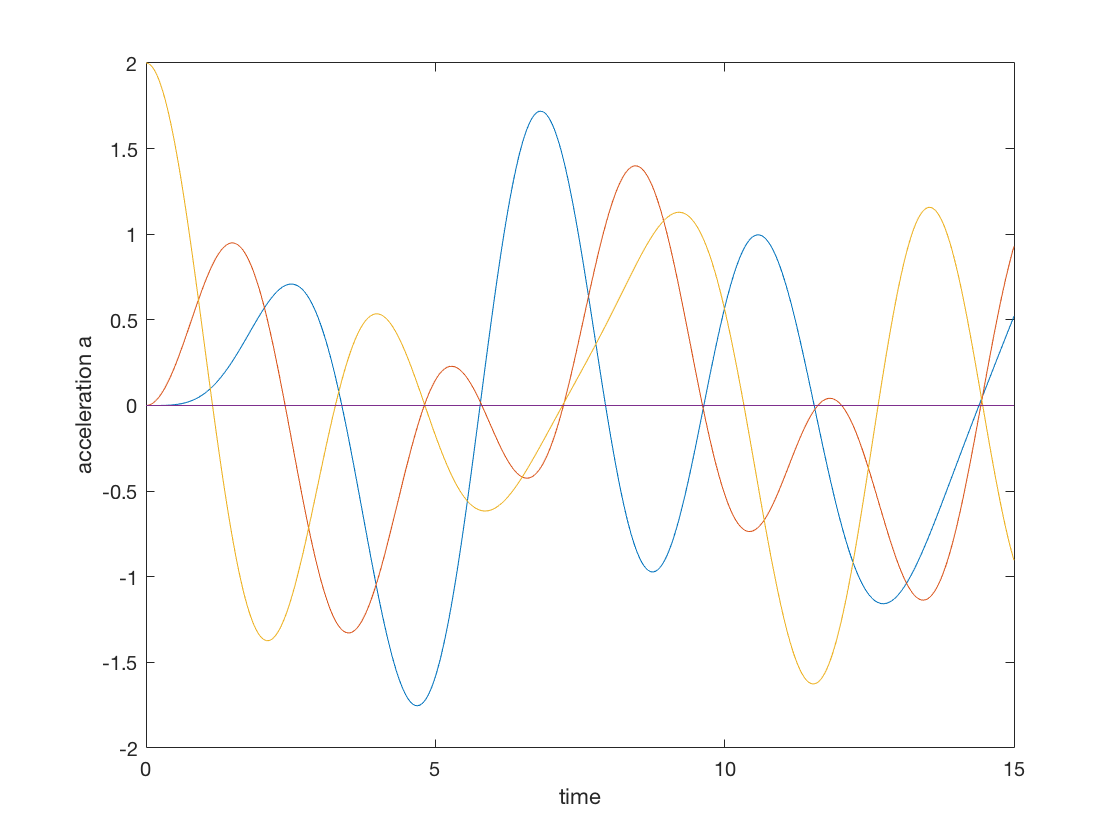


figure;
plot(t,a(:,2:end));ylabel('acceleration a');xlabel('time');

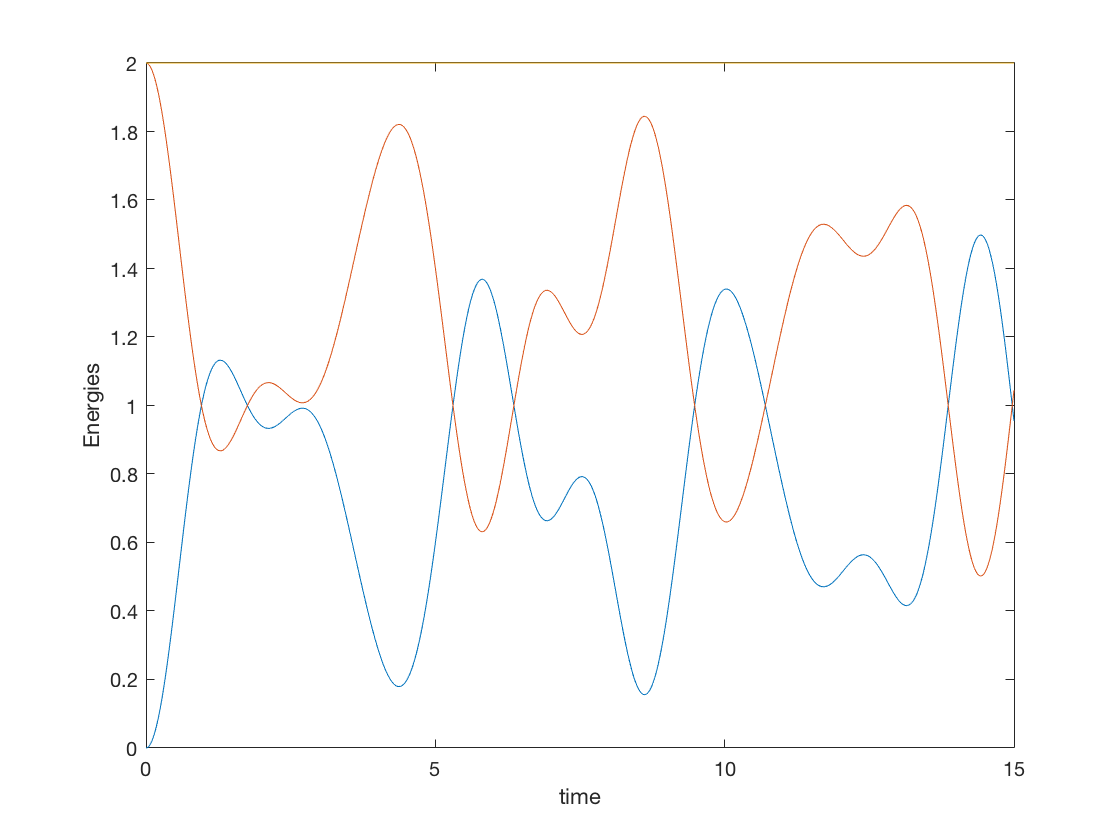


figure;
plot(t,[Ek,Ep,Etot])
ylabel('Energies');xlabel('time');